# **EXERCISE 1 : Simulate the Simplest 5G Network**

#    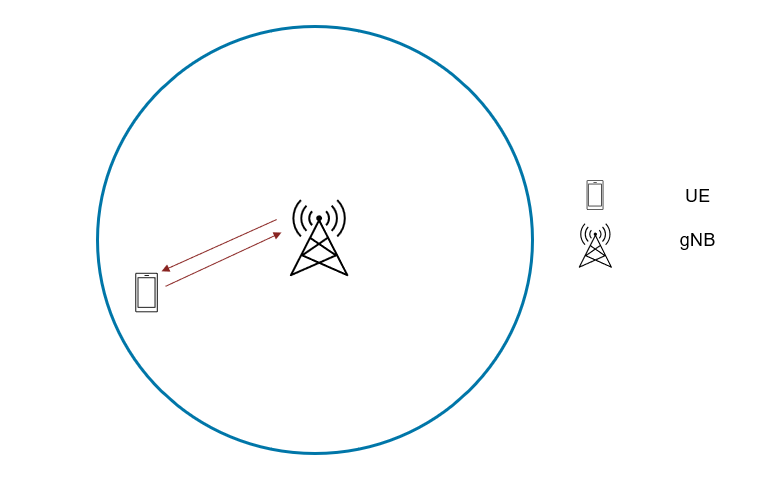

**Exercise Overview**

This exercise demonstrates a **basic 5G NR network simulation** using one **gNB (base station)** and one **UE (user equipment)**.

**Objectives:**

- Understand how to **create and configure** gNB and UE nodes.

- **Set up** a simple 5G network.

- **Simulate** the network, **capture performance statistics**, and **explore visualization tools**.

The following figure illustrates the **layers of an NR node** that can be modeled in MATLAB:

- **RLC** – Radio Link Control

- **MAC** – Medium Access Control

- **PHY** – Physical Layer

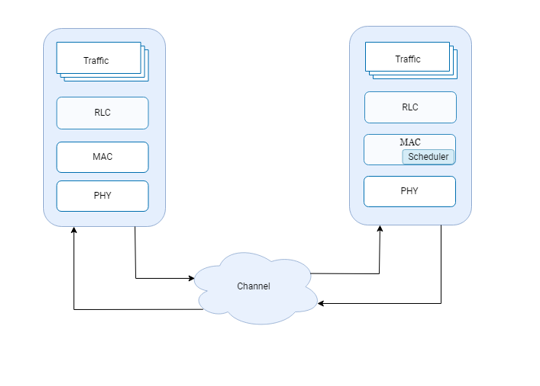

#### Close any previously opened figures and add the path to the Helpers and Utilities directories

- Reset the random number generator for reproducibility

rng("default") 
addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); 
closeFigures();

#### Initialize global variables and Wireless Network Simulator

- Initialize the Wireless Network Simulator.

- Set the NR cell radius in meters. 

- A typical urban macro cell radius from 500 to 5000 meters. 

- Specify the number of frames to simulate.

networkSimulator = wirelessNetworkSimulator.init;
cellRadius = 500; 
numFrameSimulation = 30; 
simulationTime = numFrameSimulation*0.01; 

# Task #1/3 Create a NR base station 

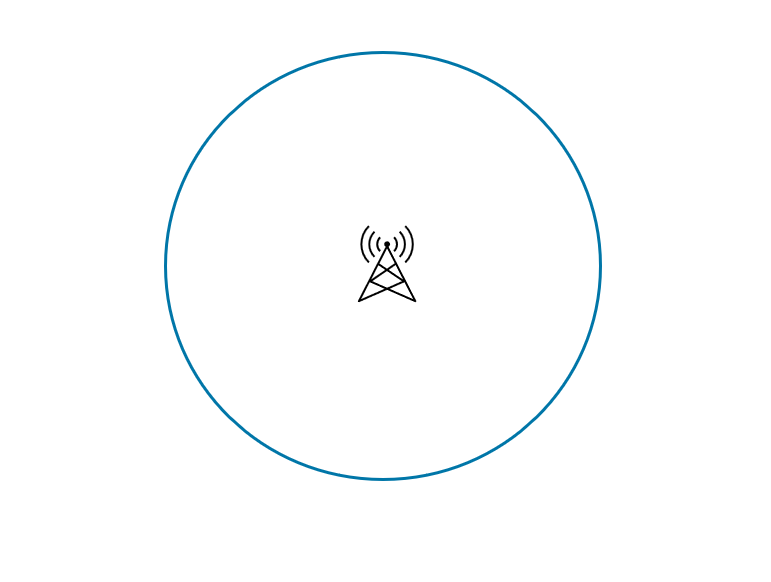

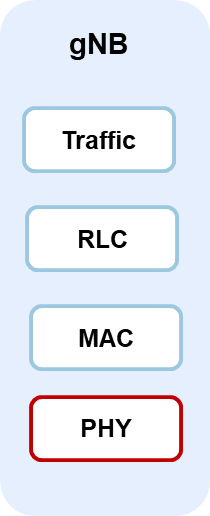

**Support for PHY****Full Physical Layer (PHY) with Waveform Processing**

- **PHYAbstractionMethod = "none"**

- Simulates the complete PHY layer: waveform generation, transmission, and reception at the sample level.

- Provides **highest accuracy**, but **requires more computation time**.

**Abstract PHY (Link-Level Abstraction)**

- **PHYAbstractionMethod = "linkToSystemMapping"**

- Builds analytical models of link quality and performance instead of simulating bits and samples.

- Leverages:

- Transmitter characteristics (power, position)

- Channel conditions (fading, interference)

- Pre-computed BER vs. SINR curves

- Enables **faster simulations** with **reasonable accuracy** for 5G network-level studies.

**Common PHY Parameters**

- **SubcarrierSpacing = 15e3** → Subcarrier spacing in Hz (up to 120e3)

- **ChannelBandwidth = 5e6** → Channel bandwidth in Hz (up to 400e6)

- **DuplexMode = "FDD"**

- *"FDD"* — Frequency Division Duplex

- *"TDD"* — Time Division Duplex

gNBPosition = [0 0 30]; 
scs=15000;
freq=2.6e9;
bw=5e6;
duplexMode="FDD";
phyAbstractionMethod="none";
% Use nrGNB() function to create a NR base station. 
% Store NR base station in a variable named "gNB"
% Note : use the following values to start with
%    Position=gNBPosition
%    SubcarrierSpacing=scs
%    CarrierFrequency=freq
%    ChannelBandwidth=bw
%    DuplexMode=duplexMode
%    PHYAbstractionMethod=phyAbstractionMethod

Hint: For detailed documentation on nrGNB(), Click the following link, and see the "Syntax" section.

[Help on creating 5G base station ](https://www.mathworks.com/help/5g/ref/nrgnb.html)

% Write your code here
gNB = nrGNB(Position=gNBPosition, ...
    SubcarrierSpacing=scs, ...
    CarrierFrequency=freq, ...
    ChannelBandwidth=bw, ...
    DuplexMode=duplexMode, ...
    PHYAbstractionMethod=phyAbstractionMethod);

#### Configure Scheduler at NR base station (gNB)

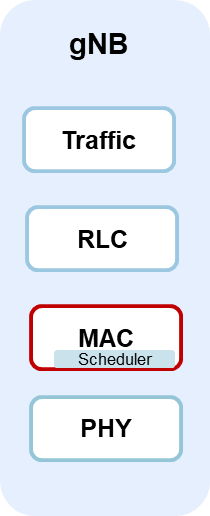

**Downlink Channel State Information (CSI) Measurement Signal**

Specifies the type of CSI measurement signal used. Choose either **"SRS"** or **"CSI-RS"**.

- **SRS (Sounding Reference Signal):** Uplink reference signal transmitted by the UE, used by the gNB to estimate uplink channel quality.

- **CSI-RS (Channel State Information Reference Signal):** Downlink reference signal transmitted by the gNB, used by the UE to measure downlink channel conditions.

**Scheduling Algorithms**

Specifies the scheduling strategy used for resource allocation among UEs.

- **"RoundRobin"** — Provides equal scheduling opportunities to all UE nodes.

- **"BestCQI"** — Prioritizes the UE node with the highest Channel Quality Indicator (CQI).

- **"ProportionalFair"** — Strikes a balance between fairness and throughput by combining aspects of both RoundRobin and BestCQI algorithms.

configureScheduler(gNB,CSIMeasurementSignalDL="CSI-RS",Scheduler="RoundRobin");

# Task #2/3 Create a NR user equipment  

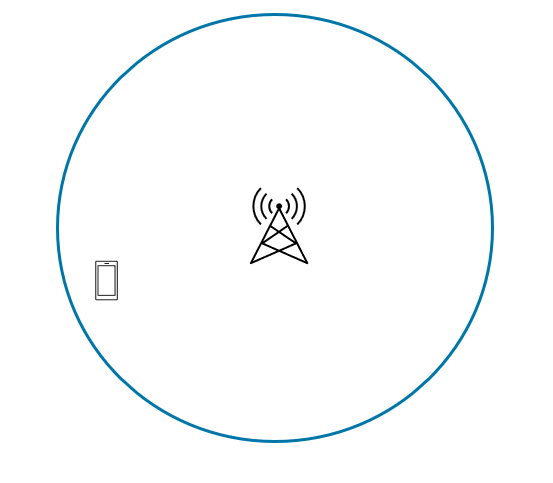

% Use nrUE() function to create a NR base station 
% Store NR base station in a variable named "UE"
% Hint:Click the following link, and see the "Syntax" section.

[Help on creating 5G user equipment ](https://www.mathworks.com/help/releases/R2025a/5g/ref/nrue.html)

% Create a UE (User Equipment) node
% Note : use the following values to start with
%    Position=uePosition
%    PHYAbstractionMethod=phyAbstractionMethod

% Write your code here
uePosition = [200 100 1]; % UE position
UE = nrUE(Position=uePosition, ...
    PHYAbstractionMethod=phyAbstractionMethod)

UE =   nrUE with properties:

                    Name: "Node2"
                Position: [200 100 1]

   Read-only properties:
             NoiseFigure: 6
             ReceiveGain: 0
           TransmitPower: 23
     NumTransmitAntennas: 1
      NumReceiveAntennas: 1
    PHYAbstractionMethod: "none"
         ConnectionState: "Idle"
                      ID: 2


# Task #3/3 Create the Network   

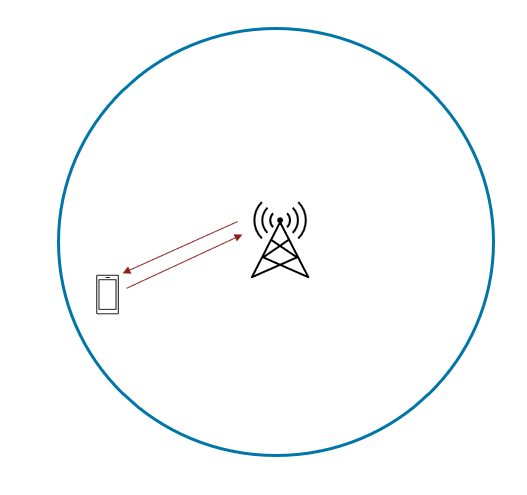

% Use connectUE() function to connect gNB to corresponding UEs
% Hint:Click the following link, and see the "Syntax" section.
% Note : use the following values to start with
% gNB 
% UE    

[Help on connecting UEs to gNB  ](https://www.mathworks.com/help/5g/ref/nrgnb.connectue.html)

% <enter code below>
connectUE(gNB, UE);

#### **Add nodes to the network simulator **

addNodes(networkSimulator, gNB);
addNodes(networkSimulator, UE);

#### **Install an application layer on gNB and UE, enable bidirectional traffic **

Application Traffic Pattern Modeling

- FTP (File Transfer Protocol) – Models file-based data transfer sessions.

- On-Off Traffic (Periodic, Bursty, or Random) – Represents intermittent data transmission patterns with varying activity periods.

- Video Streaming – Simulates continuous media flow with variable bit rates.

- Voice over IP (VoIP) – Models real-time voice communication traffic.

- Full-Buffer Traffic – Represents constant data transmission with an always-full buffer.

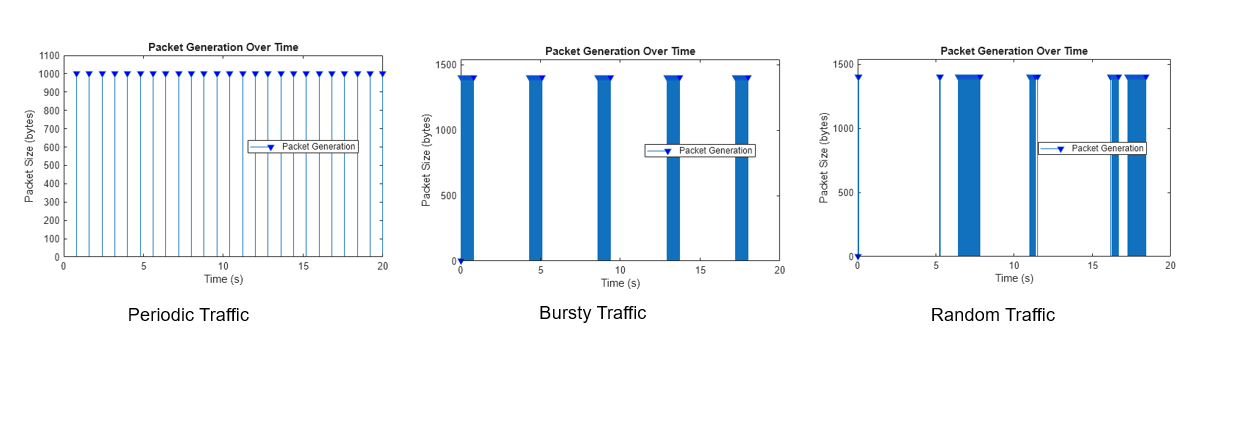

Time: 0.000000 s - Generated a periodic packet of size 1500 bytes
Time: 0.000300 s - Generated a periodic packet of size 1500 bytes
Time: 0.000600 s - Generated a periodic packet of size 1500 bytes
Time: 0.000900 s - Generated a periodic packet of size 1500 bytes
Time: 0.001200 s - Generated a periodic packet of size 1500 bytes
Time: 0.001500 s - Generated a periodic packet of size 1500 bytes
Time: 0.001800 s - Generated a periodic packet of size 1500 bytes
Time: 0.002100 s - Generated a periodic packet of size 1500 bytes
Time: 0.002400 s - Generated a periodic packet of size 1500 bytes
Time: 0.002700 s - Generated a periodic packet of size 1500 bytes
Time: 0.003000 s - Generated a periodic packet of size 1500 bytes
Time: 0.003300 s - Generated a periodic packet of size 1500 bytes
Time: 0.003600 s - Generated a periodic packet of size 1500 bytes
Time: 0.003900 s - Generated a periodic packet of size 1500 bytes
Time: 0.004200 s - Generated a periodic packet of size 1500 bytes
Time: 0.00

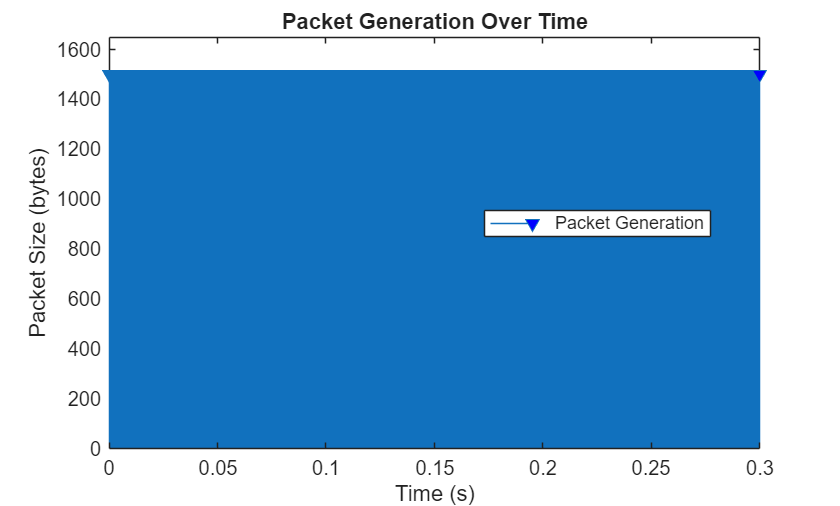

appDataRate =  40e3; % Application data rate in kilobits per second (kbps)
% Install the DL application traffic on gNB for the UE node
dlTraffic = networkTrafficOnOff(GeneratePacket=true,OnTime=Inf,OffTime=0,DataRate=appDataRate);
addTrafficSource(gNB,dlTraffic,DestinationNode=UE);
% Install the UL application traffic on the UE node for the gNB
ulTraffic = networkTrafficOnOff(GeneratePacket=true,OnTime=Inf,OffTime=0,DataRate=appDataRate);
addTrafficSource(UE,ulTraffic);
plotTrafficPattern(simulationTime,ulTraffic);

#### Add channel Model 

- The default channel model is Free Space Path Loss (FSPL).

- You can use prebuilt channel models for various deployment scenarios defined in 3GPP TR 38.901.

- You also use custom channel models 

channelModel = "FSPL";
if channelModel == "3GPP TR 38.901"
    channel = h38901Channel(Scenario="UMa");
    % Add the channel model to the simulator
    addChannelModel(networkSimulator,@channel.channelFunction);
    connectNodes(channel,networkSimulator,InterfererHasSmallScale=true);
end

#### Enable visualization, logging and IQ data capture

- Visualize the network that you have created 

- Sample rate indicates the visualization refresh rate in Hertz

- Show the cell boundary of each gNB

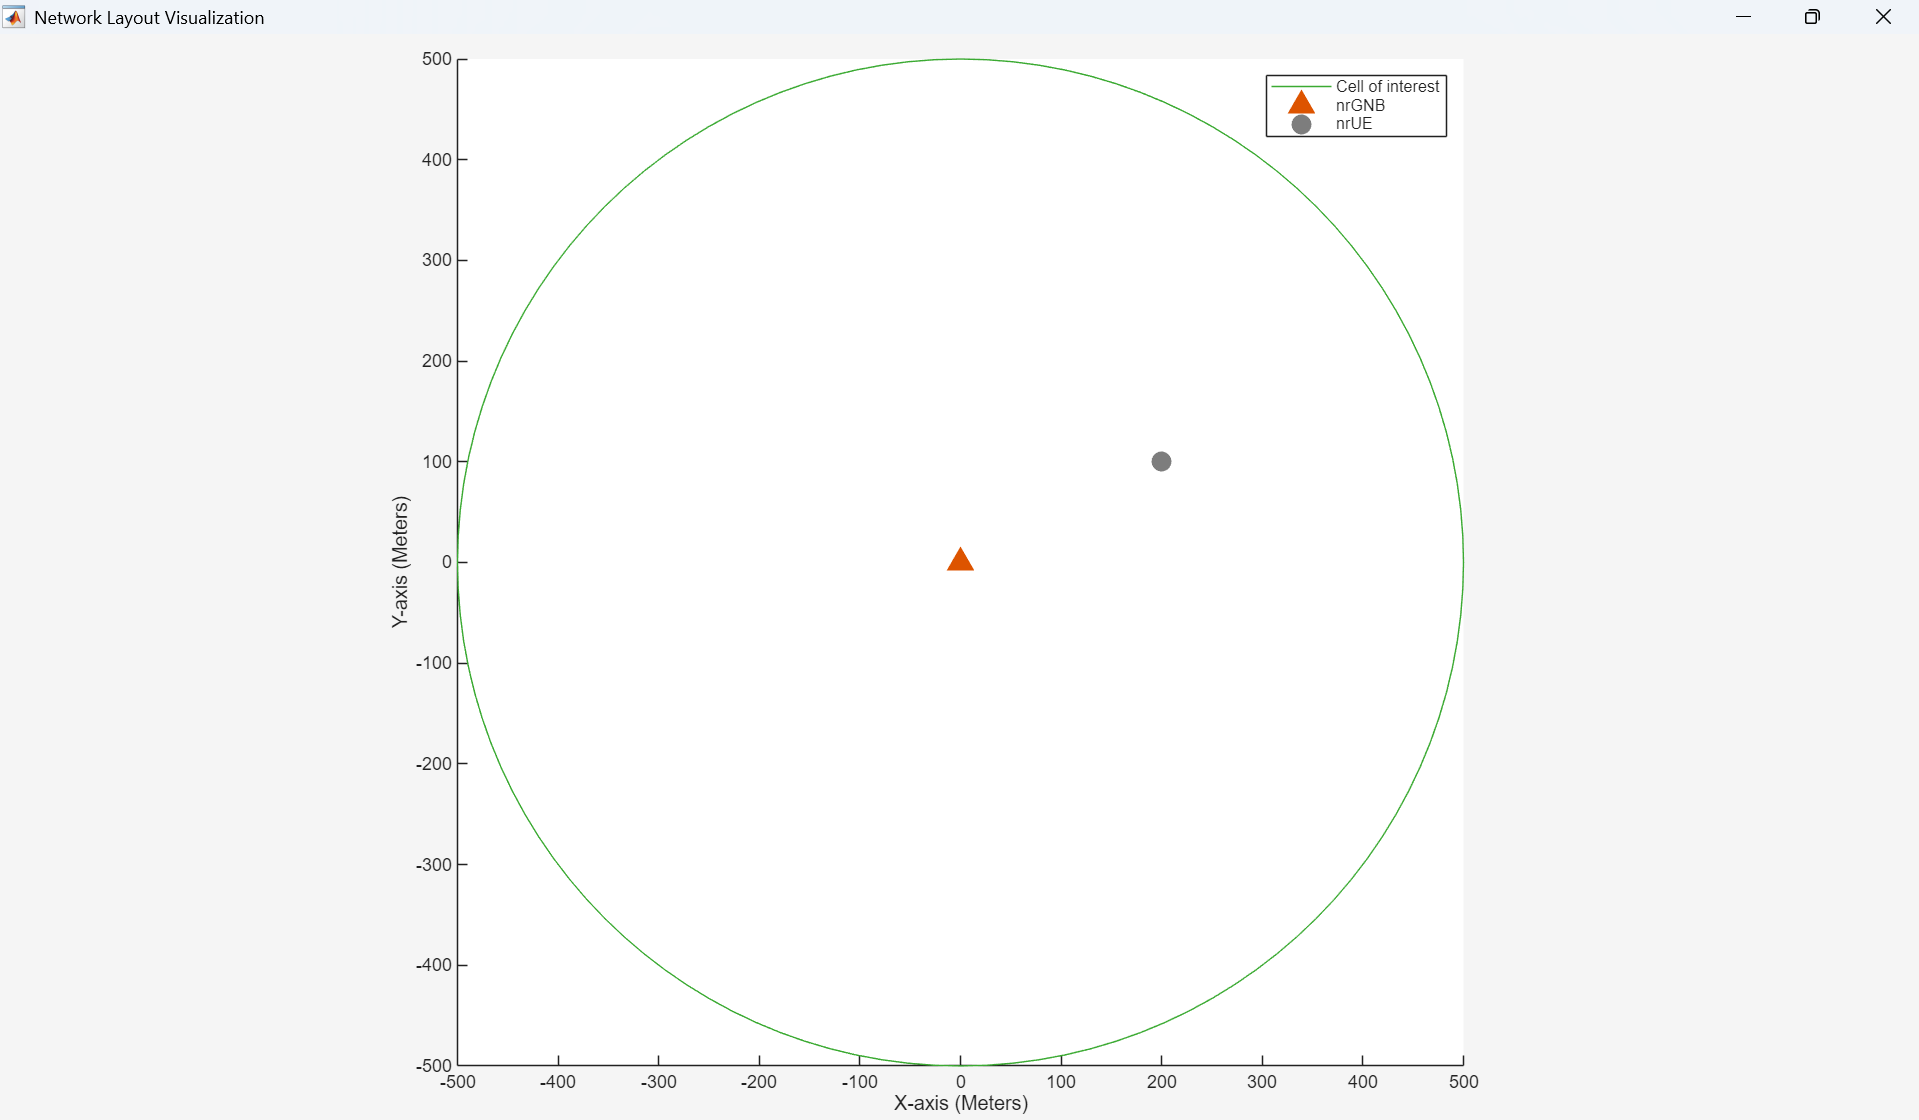

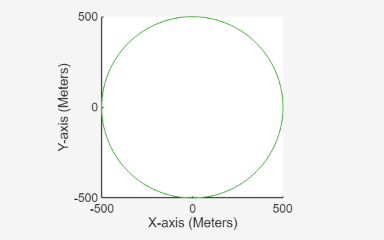

networkVisualizer = helperNetworkVisualizer(SampleRate=100); 
showBoundaries(networkVisualizer,gNBPosition,cellRadius,gNB.ID);

**Visualize PHY and MAC Performance**   

- Block Error Rate (BLER) – Ratio of erroneous blocks to total transmitted blocks.

- Transmission Rate (Tx Rate) – Data rate at which packets are transmitted.

- Throughput – Effective data rate successfully received.

- Resource Share Percentage – Portion of total radio resources allocated to each user.

- Buffer Status – Amount of data pending transmission in the buffer.

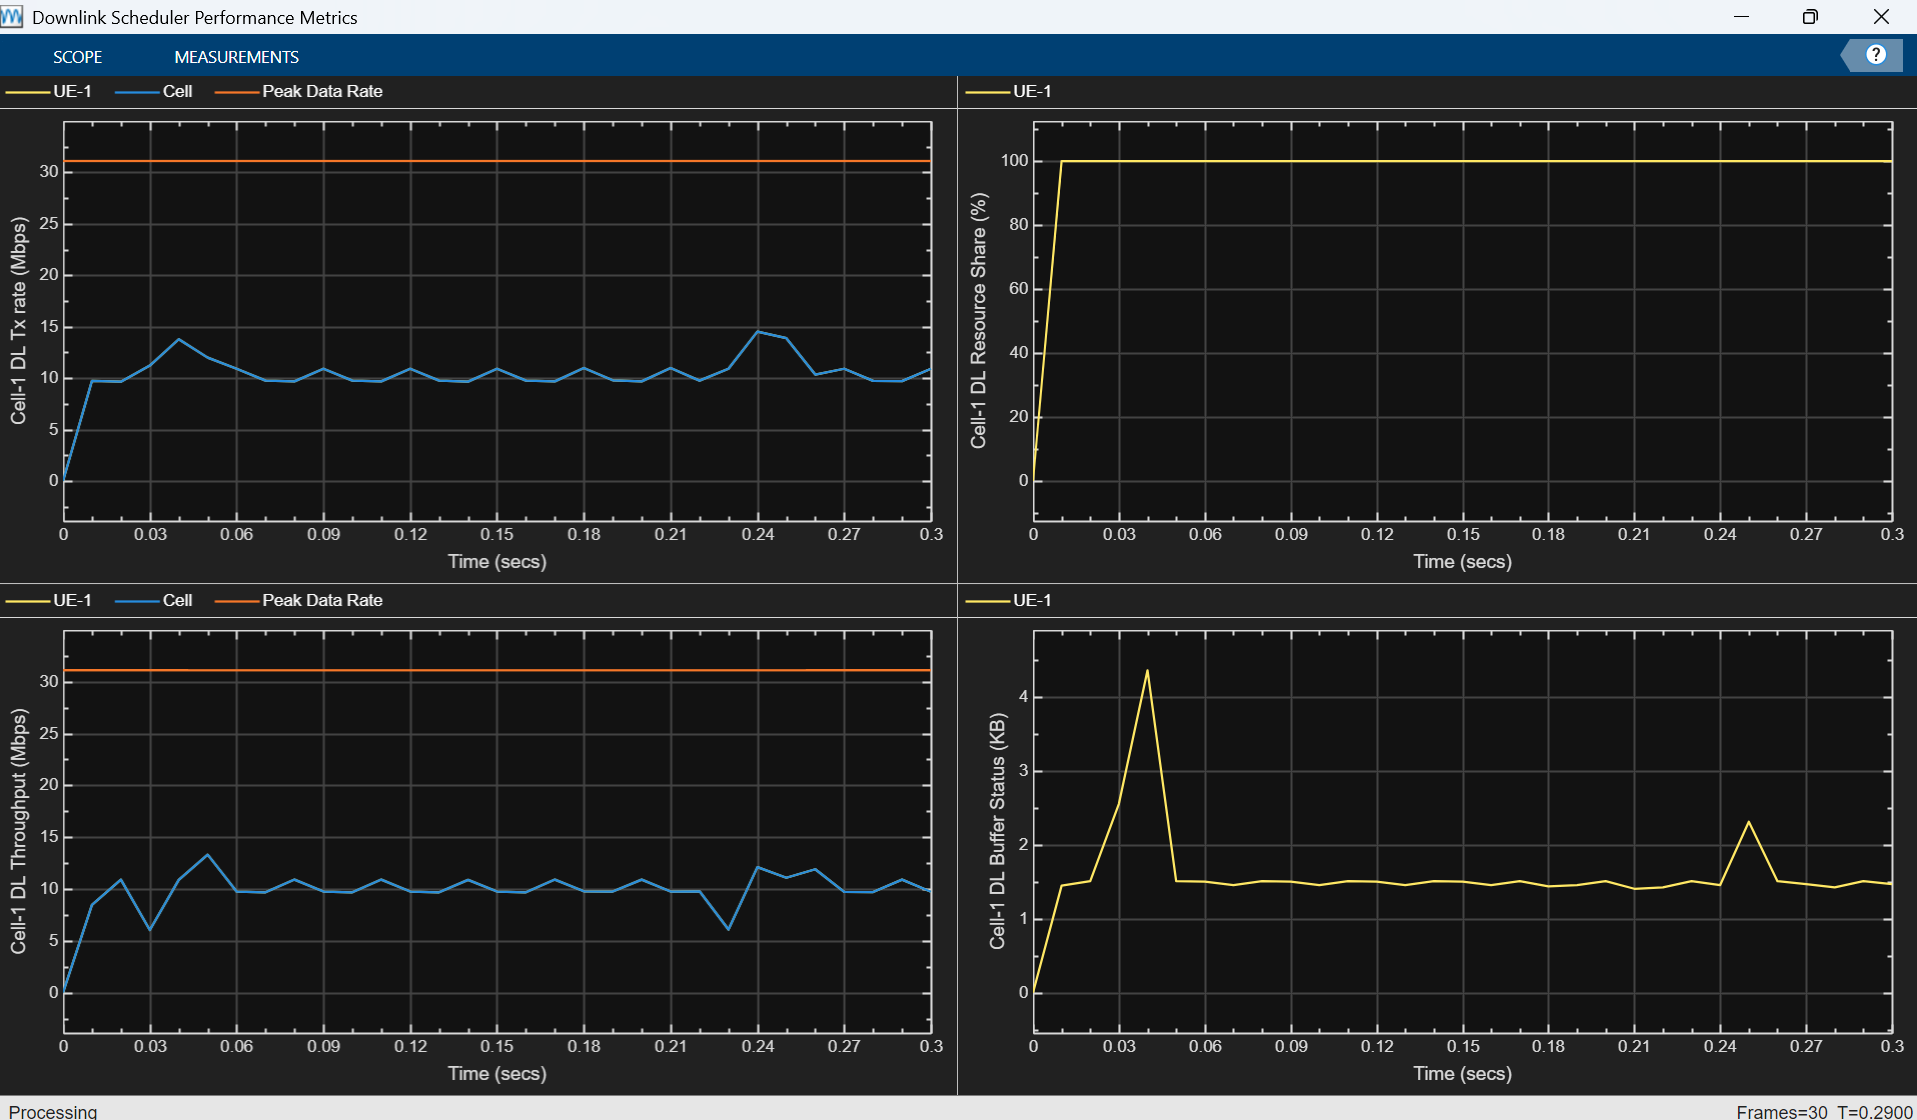

Direction  = 1;
metricsVisualizer = helperNRMetricsVisualizer(gNB,UE,RefreshRate=100,PlotSchedulerMetrics=true,PlotPhyMetrics=true,LinkDirection=Direction);

**Set up the Logger**

Simulation logs

- DLTimeStepLogs - Contains downlink time-step level information such as HARQ (Hybrid Automatic Repeat Request), CQI (Channel Quality Indicator), and resource block usage.

- ULTimeStepLogs - Contains uplink time-step level information.

- SchedulingAssignmentLogs - Includes scheduling decisions and resource allocation details.

- PhyReceptionLogs - Provides physical layer reception statistics, including decode failures along with frame, symbol, slot, and timestamp information.

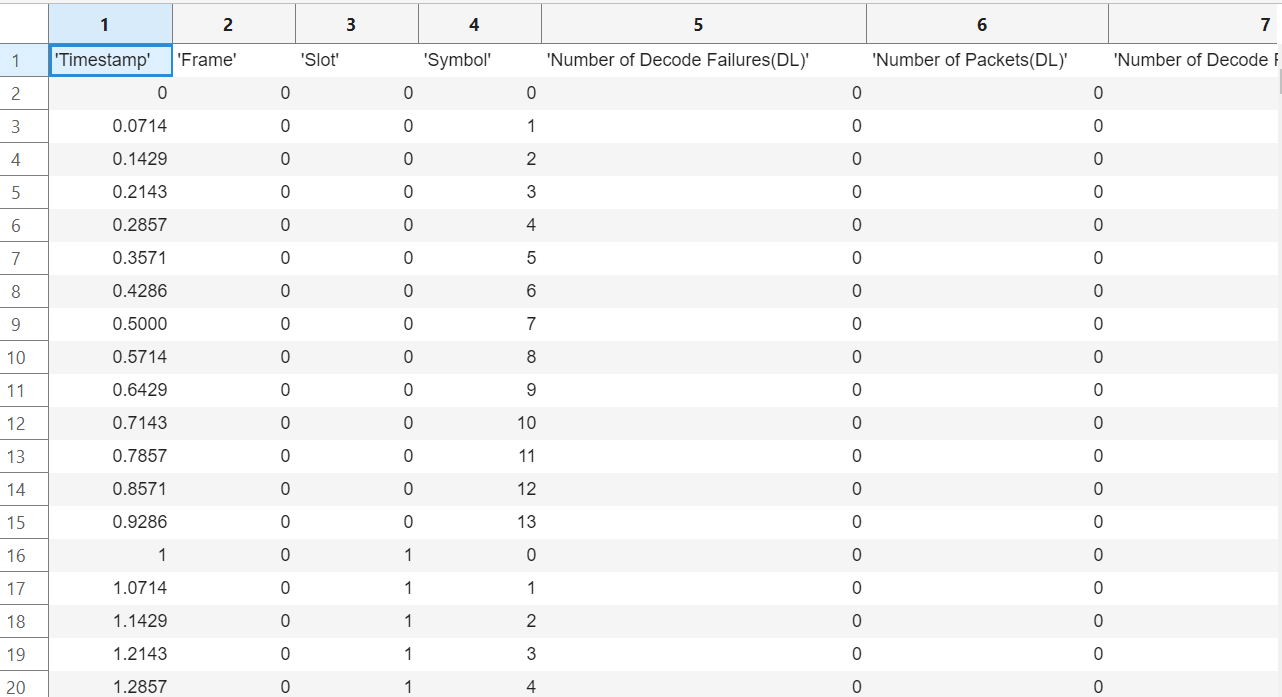

simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation,gNB,UE);
simPhyLogger = helperNRPhyLogger(numFrameSimulation,gNB,UE);
simulationLogFile = "simulationLogs"; % For logging the simulation traces

**Enable Capture of IQ Samples**

if phyAbstractionMethod == "none"
    iqSampleObj = helperCaptureIQSamples(gNB,Bandwidth=gNB.ChannelBandwidth);
end

#### Run the Simulation 

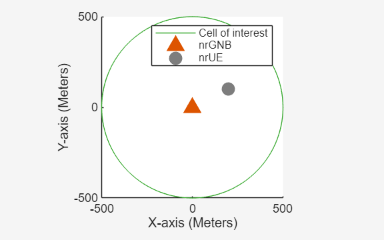

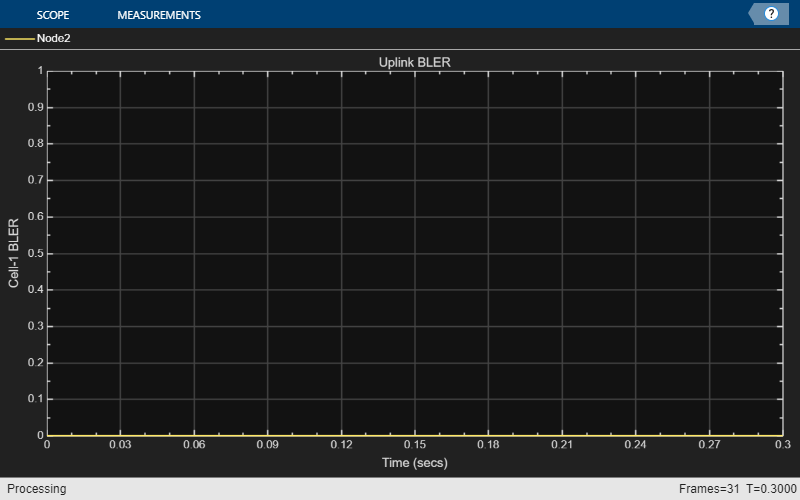

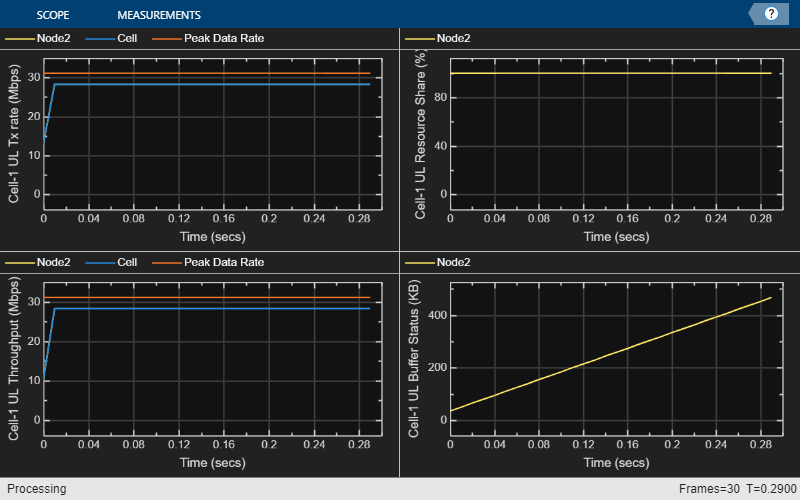

run(networkSimulator, simulationTime);

**Save Logs for all Layers **

saveTraces(networkSimulator,simSchedulingLogger,simPhyLogger,simulationLogFile);

#### Statistics of the Network 

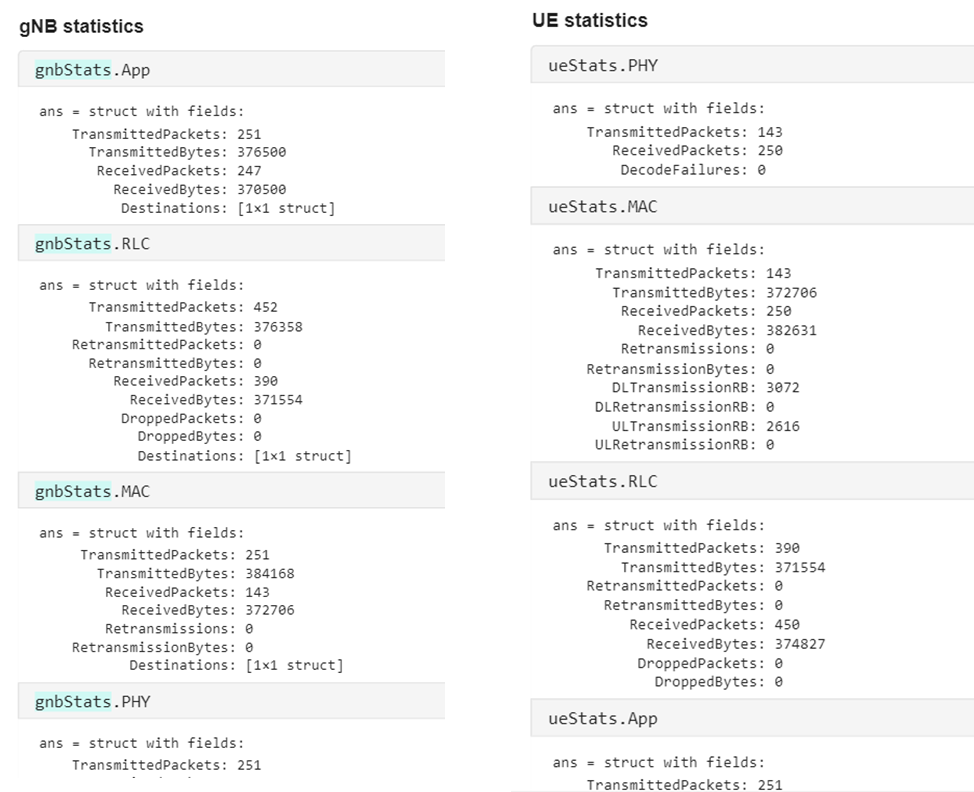

#### Get statistics from the gNB

gnbStats = statistics(gNB, "all");
fprintf(['Decode Failures (gNB): %d \n'], ...
          gnbStats.PHY.DecodeFailures);

Decode Failures (gNB): 0 


**Get statistics from UEs**

ueStats = statistics(UE);
fprintf(['Decode Failures (UE): %d \n'], ...
          ueStats.PHY.DecodeFailures);

Decode Failures (UE): 0 


#### IQ sample visualization

Visualize the waveform and spectrum.

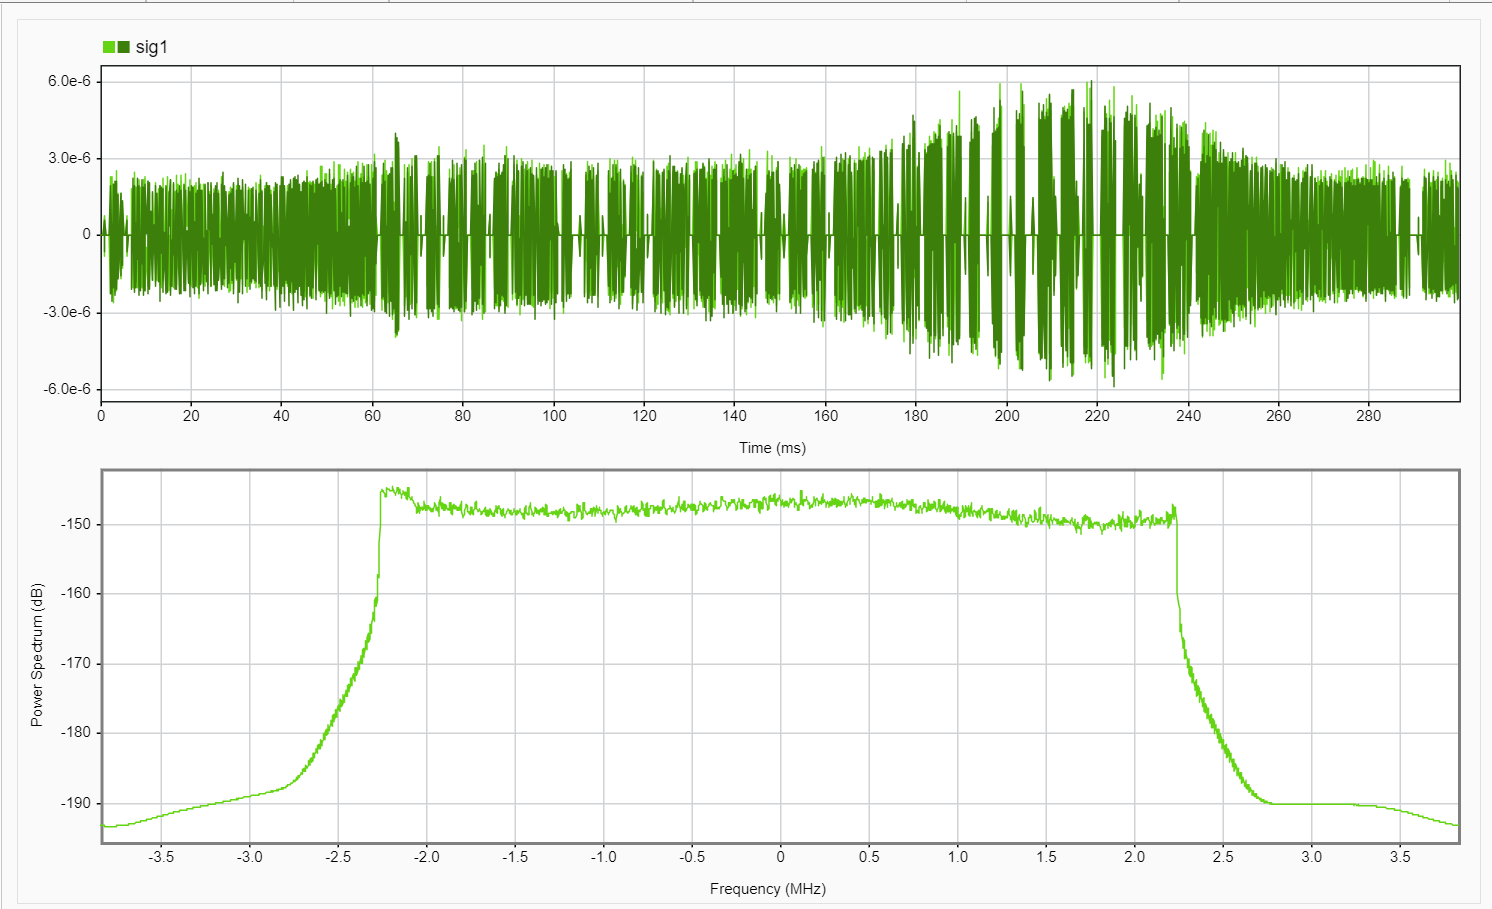

enableIQVisualization  = false;
if enableIQVisualization && phyAbstractionMethod =="none"
    signalAnalyzer(iqSampleObj.IQSamples.Data,SampleRate=7.68e6);
end

*Copyright 2025 The MathWorks, Inc.*